Inicializácia

n0 = 1;%index prveho suboru
n = 6;%pocet suborov


Vykreslenie nameraných dát

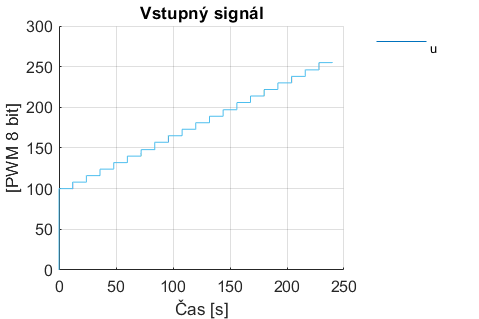

f1a = figure('Position', [100 100 900 600]);
%% obrazok f01_NameraneHodnoty
for i=n0:n0+n-1
    fileName = ['./../dataRepo/allSig_log_prev_mer',num2str(i),'_up.csv'];
    dt = csvread(fileName);
    
    txt = ['u_',num2str(i)];
    hold on;
    plot(dt(:,1),dt(:,2),'DisplayName',txt);
    hold off;
    
end
grid on; 
title('Vstupný signál');
lgd3=legend("Location",'bestoutside');
legend('_u')
lgd3.FontSize = 10;
xlabel('Čas [s]');ylabel('[PWM 8 bit]');
legend box off;

saveas(f1a, 'figures/f_01a_NameraneHodnoty.eps', 'epsc')

Error using saveas
Invalid or missing path: figures/f_01a_NameraneHodnoty.eps


f1b = figure('Position', [100 100 900 600]);
%% obrazok f01_NameraneHodnoty
for i=n0:n0+n-1
    fileName = ['./../dataRepo/allSig_log_prev_mer',num2str(i),'_up.csv'];
    dt = csvread(fileName);
    
    txt = ['y_',num2str(i)];
    hold on;
    plot(dt(:,1),dt(:,3),'DisplayName',txt);
    hold off;
end

grid on; 
title('Výstupný signál');
lgd4=legend("Location",'bestoutside');
legend('1','2','3','4','5','6')
lgd3.FontSize = 10;
xlabel('Čas [s]');ylabel('[ADC 10 bit]');
legend box off;
saveas(f1b, 'figures/f_01b_NameraneHodnoty.eps', 'epsc')


Získanie ustálených hodnôt výstupu z nameraných dát

m = 19;%predpoklad pocet derivacii vstupu (zmeny vstupu)
w = 400;%Pocet dat povaz ako ustalene
dataStore = zeros((m+1)*w,n+2);
for i=1:n
    fileName = ['./../dataRepo/allSig_log_prev_mer',num2str((n0-1)+i),'_up.csv'];
    dt = csvread(fileName);
    %dt = dt(2:end,:);
    diffVal = diff(dt(2:end,2));
    ids = find(or(diffVal > 0,diffVal < 0));    
    ln = size(ids,1);
    if ln == m
        ln = size(dt,1);
        id = [ids;ln];
        for j=1:m+1
            if i == 1
                dataStore(1+w*(j-1):w*j,1) = dt(id(j)-(w-1):id(j),1);  
                dataStore(1+w*(j-1):w*j,2) = dt(id(j)-(w-1):id(j),2);  
            end
            dataStore(1+w*(j-1):w*j,i+2) =  dt(id(j)-(w-1):id(j),3);
        end  
    end
end

Vykreslenie získaných ustálených dát

f2 = figure('Position', [100 100 900 600]);
%% f_02_VystupnyUstalenySignal
hold on;
for i=1:n
    plot(dataStore(:,1), dataStore(:,2+i),'.');
end
hold off;
grid on; 

title('Výstupný ustálený signál');
lgd=legend("Location",'bestoutside');
legend('1','2','3','4','5','6')
lgd.FontSize = 10;
xlabel('[PWM 8 bit]');
ylabel('[ADC 10 bit]');
legend boxoff;  
saveas(f2, 'figures/f_02_VystupnyUstalenySignal.eps', 'epsc')

Spriemerovanie získaných nameraných dát

Horizontálne priemerovanie

dataMean = zeros(m+1,n+1);
for i=1:n+1
    for j=1:m+1     
        if i == 1            
            dataToMean = dataStore(1+w*(j-1):w*j-1,i+1);
            dataMean(j,i) = mean(dataToMean);
        else
            dataToMean = dataStore(1+w*(j-1):w*j-1,i+1);
            dataMean(j,i) = mean(dataToMean);
        end        
    end
end

Vertikálne spriemerovanie

dataFullMean = zeros(m+1,2);
dataFullMean(:,1) = dataMean(:,1);
dt = dataMean(:,2:end)';
dataFullMean(:,2) = mean(dt);

Polyfit a polyder


[p, S] = polyfit(dataFullMean(:,1),dataFullMean(:,2),4);
[q,d] = polyder(p);
x1 = linspace(0,250,1000);
[y1,delta] = polyval(p,x1,S);
y2 = polyval(q/d,x1);

Vykreslenie

figure;

f3 = figure('Position', [100 100 900 600]);
%% f_04_PrevodovaChar
hold on;
plot(dataFullMean(:,1),dataFullMean(:,2),'.','DisplayName','Namerané dáta')
plot(x1,y1,'DisplayName','Polyfit (4. rad)');
hold off;
grid on; 
ylim([0 1000])
xlim([100 250])
title('Prevodová charakteristika');
legend("Location",'bestoutside');
xlabel('[PWM 8 bit]');ylabel('[ADC 10 bit]');
legend box off;
saveas(f3, 'figures/f_04_PrevodovaChar.eps', 'epsc')

f4 = figure('Position', [100 100 900 600]);
%%f_05_DerivaciaPrevodovejChar 
hold on;
plot(x1,y2,'DisplayName','Polyder');
hold off;
grid on; 
title('Derivácia prevodovej charakteristiky');
legend("Location",'bestoutside');
xlim([0 250])
xlabel('[PWM 8 bit]');ylabel('[ADC 10 bit]');
legend box off;
saveas(f4, 'figures/f_05_DerivaciaPrevodovejChar.eps', 'epsc')


figure;
hold on;
for i=1:n
    plot(dataMean(:,1), dataMean(:,1+i),'.');
end
hold off;
grid on; 
title('Výstupný signál');
lgd2=legend("Location",'bestoutside');
lgd2.FontSize = 13;
xlabel('Vstup (8bit) [-]');ylabel('Výstup (10 bit) [-]');
legend box off

gainData = dataFullMean(:,2)./dataFullMean(:,1);
[pGain, SGain] = polyfit(dataFullMean(:,1),gainData,4);
x1 = linspace(100,250,151);
[y1,delta] = polyval(pGain,x1,SGain);

clf;
f5 = figure('Position', [100 100 900 600]);
%% f_07_ ZavislostZosilnenieVstup
hold on;
plot(dataFullMean(:,1),gainData, 'DisplayName', 'Namerané dáta'); 
plot(x1,y1,'DisplayName','Polyfit (4. rad)');
hold off;
title('Závislosť zosilenia od vstupu');
legend('Location','bestoutside'); 
grid on; 
legend boxoff;
xlabel('[PWM 8 bit]');ylabel('Zosilnenie [-]');
saveas(f5, 'figures/f_07_ZavislostZosilnenieVstup.eps', 'epsc')